# YOUR TITLE HERE

*Authors:* MAKE SURE TO WRITE YOUR NAMES

## Generative AI (genAI) Usage Statement

Write a short statement about how you used genAI on this assignment. *Note*: If you don't write anything, we'll assume you used genAI to write the whole thing!!!

We did not use generative AI on this assignment.

*(Write your response here)*

## 1. Modeling Question

*(State your modeling question directly. Categorize it according to the action/specificity framework.)*

*(You will likely need to write 2-3 paragraphs for this section.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: we were curious about some question because of some reasons*

*B: but we weren't sure how to model it*

*T: so we did some background research for ideas (i.e. research synthesis matrix)*

*We were curious about how distance between houses impacts disease transmission, but we weren't sure how exactly to map it out, so we decided to simulate a town, Needham, and did background research.*

## 2. Literature Search

*(Identify 3 or more scholarly articles that are relevant to your modeling question. Analyze these references using the synthesis matrix approach. Report your synthesis matrix in a readable format: Include a link to a Google Sheet if it does not fit in the report.)*

*(You will likely need to write 2-3 paragraphs for this section.)*

*A: we learned X from article 1, Y from article 2, and Z from article 3*

*B: but we didn't find a direct answer to our modeling question*

*T: so we went on to build a model*

## 3. Natural World

*(Describe the natural world using your 3 or more scholarly articles. Use an inline citation every time you refer to a fact from one of the scholarly articles. Everything you describe should be relevant to your modeling question. This section should connect to your tenchi diagram; we recommend putting the diagram directly between sections 3 and 4 since it serves as a transition between the two.)*

*(You will likely need to write 2-3 paragraphs for this section.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: here's a few things that are important in the natural world*

*B: but there are some things we assumed are not relevant to our modeling question*

*T: so, we left those things outside the system boundary (they are not modeled)*

## 4. Model: Representation & Assumptions

*(Describe how your model represents the natural world. Use a tenchi diagram to illustrate what parts of the natural world are inside the system boundary. In the same tenchi diagram, provide a visual of your model. Describe in words how your model represents the chosen system. Describe in words what assumptions you have made. Cite your references when appropriate.)*

*(You will likely need to write 5-7 code & text regions for this section. You should have images and equations to describe your model, and then implement your model in code.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: this part of the natural world is important for our question*

*B: but we can't include that directly because of X reason*

*T: so here is the way we represented it / what we assumed to simplify*

*One assumption that we had was that the 120 house sample of needham that we took was accurate*

[*https://www.aimspress.com/aimspress-data/mbe/2026/7/PDF/mbe-23-07-080.pdf*](https://www.aimspress.com/aimspress-data/mbe/2026/7/PDF/mbe-23-07-080.pdf)

## 5. Verification & Validation

*(Select appropriate verification facts, and implement them as assert statements. In Projects 2 and 3, carry out model validation.)*

*(You will likely need to write 2-3 code sections for this section, and use words to describe your argument for verification and validation.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: here is a fact that should be true about the model*

*B: but it is not immediately obvious this is true, because X*

*T: so we carried out this test to show that it is true*

## 6. Claims & Limitations

*(Run simulations using your model, and make claims about the natural world based on those results. Connect each assumption to a limitation about what you *cannot* conclude based on your model.)*

*(You will likely need to write 2-3 code sections for this section [generating results with your model], and 2-3 paragraphs making claims using your results, and discussing the limitations.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: remember this assumption from Section 4*

*B: but [our model still captures X important trend OR our question is about Y specifically OR our results are still informative because of Z]*

*T: so, we can conclude X, keeping in mind Y caveats*

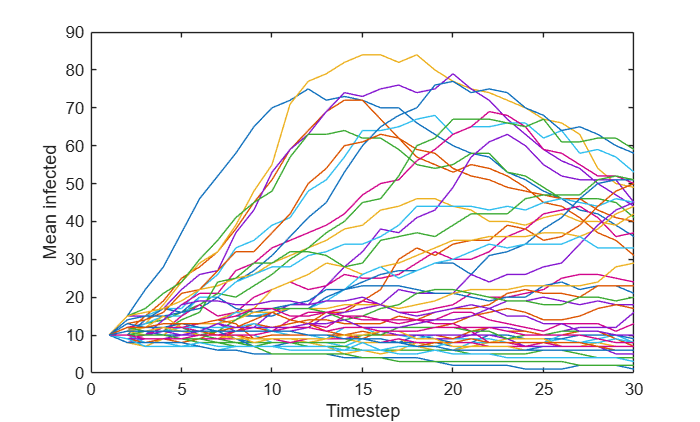


function [Sh, Ih, Rh] = simulate_absir(M, Iv0, T, infection_rate, recovery_rate)
% Simulate agent-based transmission model. Uses a graph to represent social
% connectivity between agents.
% 
% Note: You may find it helpful to summarize the state history matrices via
% summation. For instance sum(Ih, 1) will return the total number of
% infected persons at each timestep in the simulation.
%
% Inputs
%   M (square matrix): Adjacency matrix
%   Iv0 (column vector): Initial infection state
%   T (integer): Number of timesteps to simulate
%   infection_rate (float): Infection rate (probabilistic)
%   recovery_rate (float): Recovery rate (probabilistic)
% 
% Returns
%   Sh (matrix): Susceptible state history
%   Ih (matrix): Infected state history
%   Rh (matrix): Recovered state history

% Setup
dim = length(Iv0);  % Dimensions of initial state
Ih = zeros(dim, T); % Infection history
Ih(:, 1) = Iv0; % Record the initial state to infection history
Rh = zeros(dim, T); % Recovery history

% Construct an "action" helper function
    function [I, R] = action(I, R)
        % Compute infection probabilities based on the social graph
        v_eff = infection_rate * M * I;
        v_pr = v_eff ./ (1 + v_eff);

        % Draw random values
        v_infect = rand(dim, 1) <= v_pr;
        v_recover = rand(dim, 1) <= recovery_rate;

        % Infect non-recovered individuals
        I = I | v_infect & (~R);
        % Recover infected individuals
        R = R | (I & v_recover);
        I = I & (~R);
    end

% Run simulation
for i = 2:T
    [Ih(:, i), Rh(:, i)] = action(Ih(:, i-1), Rh(:, i-1));
end

% Compute susceptible history
Sh = ones(dim, T) - Ih - Rh;
end


function strength = distancetostrength(d)
strength = exp(-d/50); 
%strength = 1/(1+d);
end 

function M_res = make_adj_pods(n_per_pod, n_pods, dBlock)
% Construct an adjacency matrix for a "podding" scenario
%
% Usage
%   M_res = make_adj_pods(n_per_pod, n_pods, infectivity)
%
% Arguments
%   n_per_pod  = number of persons per "pod"
%   n_pods     = total number of pods; total population = n_per_pod * n_pods
%   pod_effect = relative infectivity within pods; should be infectivity > 1
%
% Returns
%   M_res = adjacency matrix for desired graph
n_total = n_per_pod * n_pods;

% Create the "base matrix" with weak connections between all persons
M_res =  distancetostrength(dBlock)* (ones(n_total, n_total) - eye(n_total));

% Add the pod structure
for i = 1:n_pods
    % Determine the slicing indices
    i0 = (i - 1) * n_per_pod + 1; ie = i0 + n_per_pod - 1;
    % Assign strong in-pod weights
    M_res(i0:ie, i0:ie) = 10 * M_res(i0:ie, i0:ie);
end

end






% x = zeros(120,1);
% for i = 1:120
%     prob = rand * 12;
%     if prob > 1
%         x(i) = 0;
%     end 
%     if prob < 1
%         x(i) = 1;
%     end 
% end 

initial_state = zeros(120, 1);
initial_state(1:10) = 1;



t_end = 30;
infection_rate = 0.005;
recovery_rate = 0.05;

% number of different distances
num_steps = 50;

% range of possible distances
min_distance = 50; max_distance = 200;

% array of possible distances
distance_vals = linspace(min_distance, max_distance, num_steps);
I_temp = zeros(num_steps, t_end);
% simulate each distance
for k = 1:num_steps
    adj_matrix = make_adj_pods(20, 6, distance_vals(k));
    for t = 1:t_end
        [~, Ih, ~] = simulate_absir(adj_matrix, initial_state, t_end, infection_rate, recovery_rate);
        I_temp(k,:) = sum(Ih, 1);
    end
end

figure
plot(1:30, I_temp')
xlabel('Timestep'); ylabel('Mean infected')

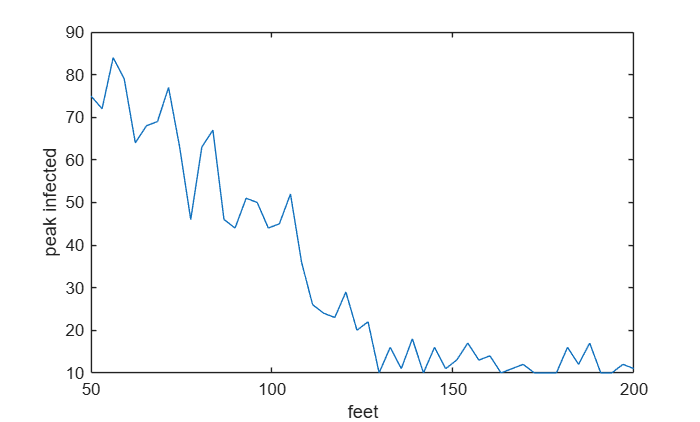

peaks = max(I_temp, [], 2);

figure
plot(distance_vals, peaks)
xlabel('feet'); ylabel('peak infected')

## 7. Conclusion

*(Restate your modeling question, and refer to the claims from Section 6. Use your claims to directly answer your modeling question.)*

*(You will likely need just 1 paragraph for this section.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: this part of the natural world is important, and X is already known*

*B: but Y is not yet known, so we built a model to answer the question ...*

*T: so, given [particular result from Section 6], we conclude Z*

## 8. Future Work

*(Based on your limitations from Section 6, state 2 or more ideas of future work for other modelers to attempt.)*

*(You will likely need 2-3 paragraphs for this section.)*

*Suggested template: **FOR INSPIRATION, NOT TO USE DIRECTLY**.*

*A: our model assumed X*

*B: but the natural world is actually like Y*

*T: so there are open questions, such as Z*

## References

*(List all references alphabetically by last name. Use the following format: Last name 1, Last name 2, ... (Year) "Title of Reference")*